Create taylorpolyexample.gif

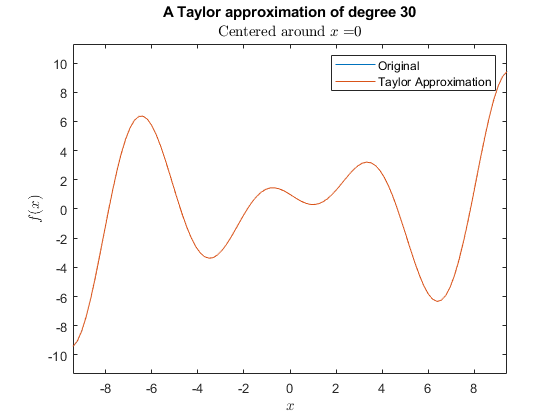

syms F(x)
F(x) =  sin(x)/x-x*cos(x);
x0 =  0;
bds = [-3*pi,3*pi];
vals = ones(10,1).*(1:30);
%vals = 1:30;
Tlast = showTaylor(@(x)F(x),vals(1:end),bds,x0);

disp(Tlast)

$$1-x-\frac{x^{2}}{6}+\frac{x^{3}}{2}+\frac{x^{4}}{120}-\frac{x^{5}}{24}-\frac{x^{6}}{5040}+\frac{x^{7}}{720}+\frac{x^{8}}{362880}-\frac{x^{9}}{40320}-\frac{x^{10}}{39916800}+\frac{x^{11}}{3628800}+\frac{x^{12}}{6227020800}-\frac{x^{13}}{479001600}-\frac{x^{14}}{1307674368000}+\frac{x^{15}}{87178291200}+\frac{x^{16}}{355687428096000}-\frac{x^{17}}{20922789888000}-\frac{x^{18}}{121645100408832000}+\frac{x^{19}}{6402373705728000}+\frac{x^{20}}{51090942171709440000}-\frac{x^{21}}{2432902008176640000}-\frac{x^{22}}{25852016738884976640000}+\frac{x^{23}}{1124000727777607680000}+\frac{x^{24}}{15511210043330985984000000}-\frac{x^{25}}{620448401733239439360000}-\frac{x^{26}}{10888869450418352160768000000}+\frac{x^{27}}{403291461126605635584000000}+\frac{x^{28}}{8841761993739701954543616000000}-\frac{x^{29}}{304888344611713860501504000000}-\frac{x^{30}}{8222838654177922817725562880000000}$$

function T = showTaylor(fh,deg,bds,x0)
arguments
    fh function_handle
    deg (1,:) {mustBePositive,mustBeFinite,mustBeInteger}
    bds (1,2) {mustBeNumeric}
    x0 (1,1) {mustBeNumeric,mustBeFinite}
end
if length(deg) > 1
    for k = 1:length(deg)
        T = calcTaylor(fh,deg(k),bds,x0);
        pause(0.5)
    end
else
    T = calcTaylor(fh,deg,bds,x0);
end

end

function T = calcTaylor(fh,deg,bds,x0)
% calcTaylor computes and plots a Taylor polynomial approximation
%   fh is a function handle
%   deg is the degree of the Taylor polynomial
%   bds are the x limits of the range to be plotted
%   x0 is the center value for the approximation, x=x0
syms x
T = taylor(fh(x),x,"ExpansionPoint",x0,"Order",deg+1);
xVals = linspace(bds(1),bds(2),100);
fVals = fh(xVals);
plot(xVals,fVals);
hold on
TVals = double(subs(T,x,xVals));
plot(xVals,TVals);
hold off
title("A Taylor approximation of degree " + deg)
subtitle("Centered around $x =$" + x0,"Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$f(x)$","Interpreter","latex")
scale = double((max(fVals)-min(fVals)))*0.1;
ylim(double([min(fVals)-scale max(fVals)+scale]))
xlim(bds)
legend(["Original" "Taylor Approximation"],"Location","northeast")
end
